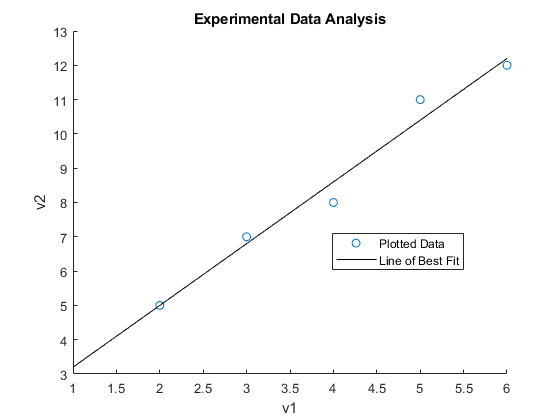

%Problem 1
clear
clc
v1 = [2, 3, 4, 5, 6];
v2 = [5, 7, 8, 11, 12];
x = v1;
y = v2;
A = [ones(length(x), 1), x'];
b = y';

[c2, c1] = LSSolver(A, b);
x_vec = linspace(1, 6);

lin_fit = (c2 * x_vec) + (c1);
scatter(x, y, "o");
title("Experimental Data Analysis")
xlabel("v1")
ylabel("v2")
hold on;
plot(x_vec, lin_fit, "k");
legend("Plotted Data", "Line of Best Fit", "Location", "best")
hold off

function [c2, c1] = LSSolver(A, b)
    x_ls = (A' * A) \ (A' * b);
    c2 = x_ls(2);
    c1 = x_ls(1);
end

for v1 = 4.6, v2 = 9.7